addpath(genpath('~/Documents'));

%% Create bone structure 
bones = {'271G' '267G' '251G' '245D' '227G'};
min_slices = [0, 0, 761, 470, 1210];
max_slices = [0, 0, 2125, 1861, 2793];
T = table(min_slices', max_slices', 'VariableNames', {'min_slice', 'max_slice'}, 'RowNames', bones);

% Get bone

`Select the bone : `

bone = '227G';
dirname = ['~/Documents/BoneRugosity/RMS/BoneSample/', bone, '/'];

min_slice = T{bone, 'min_slice'};
max_slice = T{bone, 'max_slice'};

`Select the slice :`

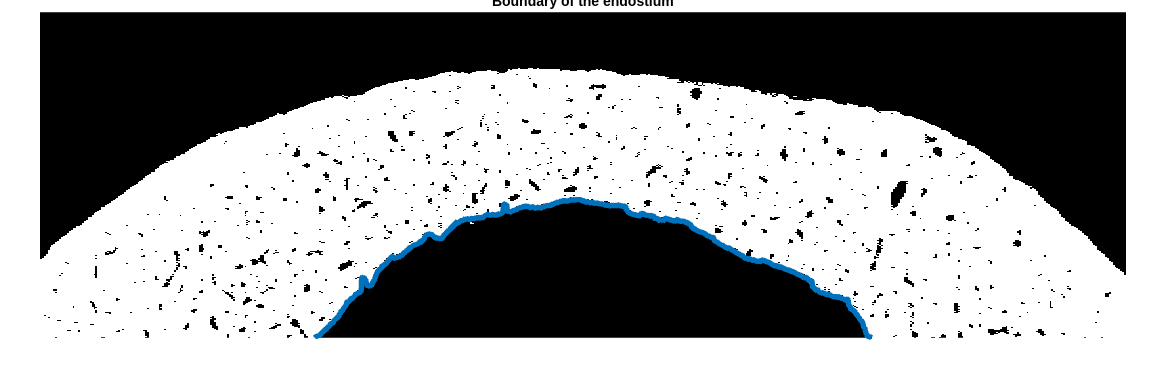

num_slice = 1590;

file = ['SAMPLE_', bone, '_SLICE_', sprintf('%04d', num_slice), '.bmp']; 
filename = [dirname, file];
% BOUNDARIES COMPUTATION

bone_bmp = imread(filename); 
threshold = graythresh(bone_bmp); % Find an automatic threshold
binaryImage = imbinarize(bone_bmp, threshold);

segmented = false;
boundaryEndost = ExtractBoundary(filename, segmented);
figure
imshow(binaryImage);
hold on;
plot(boundaryEndost(1, :), boundaryEndost(2, :), 'LineWidth', 4);  
hold on;
xlabel('Width');
ylabel('Depth');
grid on
title('Boundary of the endostium'); hold off;


boundaryEndost(2, :) = max(boundaryEndost(2, :)) - boundaryEndost(2, :);

%% COMPUTE FOURRIER TRANSFORM OF THE PROFILE
% Parameters
delta_x = 9e-3;             % Pixel size corresponding to the space step (mm)
Fs = 1/delta_x;             % Sampling frequency (mm-1)
L = size(boundaryEndost, 2);

% Initial profile
profile = boundaryEndost(2, 2:end) * delta_x; % - mean(boundary_endost(2, :));

x = (0:L-1)*1/Fs;

%% WITH BUILT-IN FUNCTION 

Select the cut off frequency 

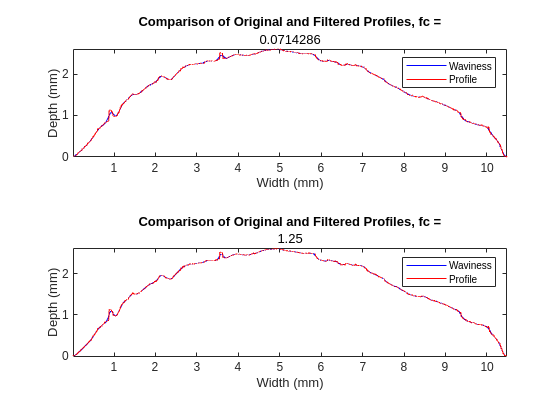

kc =  2.5e6/(10*3500e3);
waviness = lowpass(profile,kc,Fs);
roughness = highpass(profile, kc, Fs);

figure
subplot(2,1,1)
plot(x(1, 2:end), real(waviness), 'b', 'DisplayName', 'Waviness');
hold on
plot(x(1, 2:end), profile, 'r', 'DisplayName', 'Profile');
title('Comparison of Original and Filtered Profiles, fc =', kc);
xlabel('Width (mm)');
ylabel('Depth (mm)');
legend();
hold off
axis image
subplot(2,1,2)
plot(x(1, 2:end), real(lowpass(profile,1.25,Fs)), 'b', 'DisplayName', 'Waviness');
hold on
plot(x(1, 2:end), profile, 'r', 'DisplayName', 'Profile');
title('Comparison of Original and Filtered Profiles, fc =', 1.25);
xlabel('Width (mm)');
ylabel('Depth (mm)');
legend();
hold off
axis image

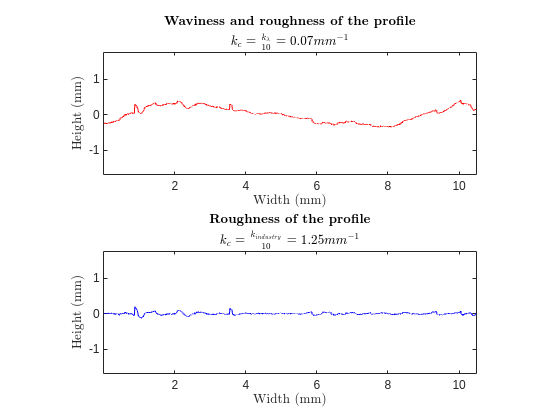

figure
subplot(2,1,1)
plot(x(1, 2:end), roughness, 'r');
title('\bf Waviness and roughness of the profile', '$k_c = \frac{k_{\lambda}}{10} = 0.07 mm^{-1}$', 'Interpreter', 'latex');
xlabel('Width (mm)', 'Interpreter', 'latex');
ylabel('Height (mm)', 'Interpreter', 'latex');
axis equal
subplot(2,1,2)
plot(x(1, 2:end), highpass(profile, 1.25, Fs), 'b');
title('\bf Roughness of the profile', '$k_c = \frac{k_{industry}}{10} = 1.25 mm^{-1}$', 'Interpreter', 'latex');
xlabel('Width (mm)', 'Interpreter', 'latex');
ylabel('Height (mm)', 'Interpreter', 'latex');
axis equal

rms_fc = rms(roughness);
rms_8 = rms(highpass(profile, 1.25, Fs));
fprintf('With fc = 0.06mm-1, Rms = %.2f um \nWith fc = 1.25mm-1, Rms = %.2f um', rms_fc*1e3, rms_8*1e3);

With fc = 0.06mm-1, Rms = 213.72 um 
With fc = 1.25mm-1, Rms = 32.59 um

frequencies = logspace(log10(1e-3), log10(50), 50);

SigFreqBone = 2.5e6/3500e3;        % Frequency (mm-1) that corresponds to the wavelenght in bone 

frequencies_lambda = [SigFreqBone, SigFreqBone/10, SigFreqBone/100, SigFreqBone*10];
parameters = zeros(3, length(frequencies));

for i = 1 : length(frequencies)
    [profile, roughness, xProfile] = GetRoughness(filename, frequencies(i), false);
    parameters(1, i) = rms(roughness);
    parameters(2, i) = trapz(roughness);
    parameters(3, i) = mean(roughness);
end

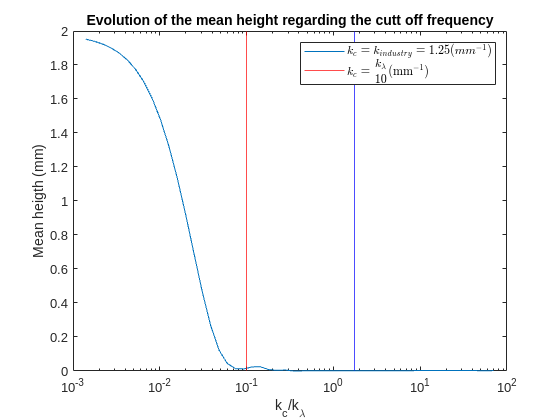


% Expression of the frequencies regarding the frequency that corresponds to
% the bone wavelength. 
frequencies = frequencies/SigFreqBone;

figure
% subplot(1,2,1)
% semilogx(frequencies, parameters(1, :));
% hold on 
% xline(fc/SigFreqBone, 'r');
% xline(1.25/SigFreqBone, 'b');
% hold off
% title('Evolution of the RMS regarding the cutt off frequency');
% xlabel('Cutt off frequency expressed in bone wavelength');
% ylabel('RMS (mm)');

% subplot(1,2,2)
semilogx(frequencies, parameters(3, :));
hold on 
xline(kc/SigFreqBone, 'r');
xline(1.25/SigFreqBone, 'b');
hold off
title('Evolution of the mean height regarding the cutt off frequency');
ylabel('Mean heigth (mm)');
xlabel('k{_c}/k{_\lambda}');
legend('$k_c = k_{industry} = 1.25 (mm^{-1})$', '$$k_c = \frac{k_{\lambda}}{10} \mathrm{(mm^{-1})}$$', 'Interpreter', 'latex');